# MTH 4800 Numerical Analysis I Programming Assignment 7

## Jarred Maestas

### Numerical Integration

1. (20pts) Write one program incorporating the composite methods for trapezoidal, midpoint, and Simpson’s rules. Comment it thoroughly and turn it in. Input for the program will consist of the integrand, the ends of the integration interval, and the number of (uniform) subintervals. Then, Incorporate the Gauss- Legendre quadrature points and weights to write a computation for Gaussian Quadrature also. There is a code for these points and weights by Lloyd Trefethen [?].) Keep in mind, you will need to do a transformation to convert $[a, b]$ to $[-1, 1]$ when you apply the Gaussian quadrature rule. Then, apply your program to the following integrals and evaluate the following points:

- Use $n = 2, 4, 8, 16, 32$ subintervals for your composite methods (apply the quadrature method for each of these cases so you can compare the approximations as h decreases.)

- For each of the integrals, explain the behavior of the error by observing how it is reduced each time the number of subintervals is doubled (as n is doubled).

- Graph your error on a loglog scale as described in the text and evaluate the rate of convergence from this plot.

- Compare the error with its analytical bounds for each method.

- Compare the performance of the methods (accuracy and efficiency). Take into consideration both the error and the number of function evaluations. Built-in functions like tic and toc (in MATLAB) will allow you to time each evaluation for a comparison of computational speed. Discuss your results; how each method performed and what you would recommend using based on these results.

Problem a) 4/(1+x^2) on [0,1]


Exact value: 3.141592653589793


n      Midpoint Error     Trapezoidal Error  Simpson Error      Gauss Error       


2      2.0760287587e-02   4.1592653590e-02   8.2593202565e-03   1.7239441232e-05  
4      5.2078648041e-03   1.0416183002e-02   2.4026138813e-05   1.0746850965e-07  
8      1.3020760019e-03   2.6041590987e-03   1.5113108631e-07   1.6817538473e-09  
16     3.2552071877e-04   6.5104154840e-04   2.3649713299e-09   2.6281643528e-11  
32     8.1380206544e-05   1.6276041482e-04   3.6956659955e-11   4.1078251911e-13  



Error Reduction Factor (when n doubles)


n      Midpoint     Trapezoidal  Simpson      Gauss       


4      3.9863       3.9931       343.7639     160.4139    
8      3.9997       3.9998       158.9755     63.9026     
16     4.0000       4.0000       63.9040      63.9897     
32     4.0000       4.0000       63.9931      63.9795     



Expected reduction factors:


  Midpoint/Trapezoidal: ~4 (O(h^2) methods)


  Simpson: ~16 (O(h^4) method)



Convergence Order (from loglog slope)


Midpoint Rule:     slope = 1.9990 (theoretical: -2)


Trapezoidal Rule:  slope = 1.9995 (theoretical: -2)


Simpson's Rule:    slope = 6.8782 (theoretical: -4)


Gauss-Legendre:    slope = 6.2643



Comparison with Analytical Error Bounds


Estimated max |f''(x)|:  7.999944e+00


Estimated max |f^(4)(x)|: 9.599485e+01



n      Trap Bound         Trap Actual        Simp Bound         Simp Actual       


2      1.6666549767e-01   4.1592653590e-02   3.3331545749e-02   8.2593202565e-03  
4      4.1666374417e-02   1.0416183002e-02   2.0832216093e-03   2.4026138813e-05  
8      1.0416593604e-02   2.6041590987e-03   1.3020135058e-04   1.5113108631e-07  
16     2.6041484011e-03   6.5104154840e-04   8.1375844113e-06   2.3649713299e-09  
32     6.5103710027e-04   1.6276041482e-04   5.0859902571e-07   3.6956659955e-11  



Performance Comparison (Accuracy and Efficiency)


n      Method       Evals      Time (s)     Error       


2      Midpoint     2          1.349750e-03 2.0760e-02  


       Trapezoidal  3          1.349750e-03 4.1593e-02  


       Simpson      3          1.349750e-03 8.2593e-03  


       Gauss        4          1.349750e-03 1.7239e-05  



4      Midpoint     4          1.549375e-04 5.2079e-03  


       Trapezoidal  5          1.549375e-04 1.0416e-02  


       Simpson      5          1.549375e-04 2.4026e-05  


       Gauss        8          1.549375e-04 1.0747e-07  



8      Midpoint     8          3.245417e-04 1.3021e-03  


       Trapezoidal  9          3.245417e-04 2.6042e-03  


       Simpson      9          3.245417e-04 1.5113e-07  


       Gauss        16         3.245417e-04 1.6818e-09  



16     Midpoint     16         8.994167e-04 3.2552e-04  


       Trapezoidal  17         8.994167e-04 6.5104e-04  


       Simpson      17         8.994167e-04 2.3650e-09  


       Gauss        32         8.994167e-04 2.6282e-11  



32     Midpoint     32         1.958552e-03 8.1380e-05  


       Trapezoidal  33         1.958552e-03 1.6276e-04  


       Simpson      33         1.958552e-03 3.6957e-11  


       Gauss        64         1.958552e-03 4.1078e-13  



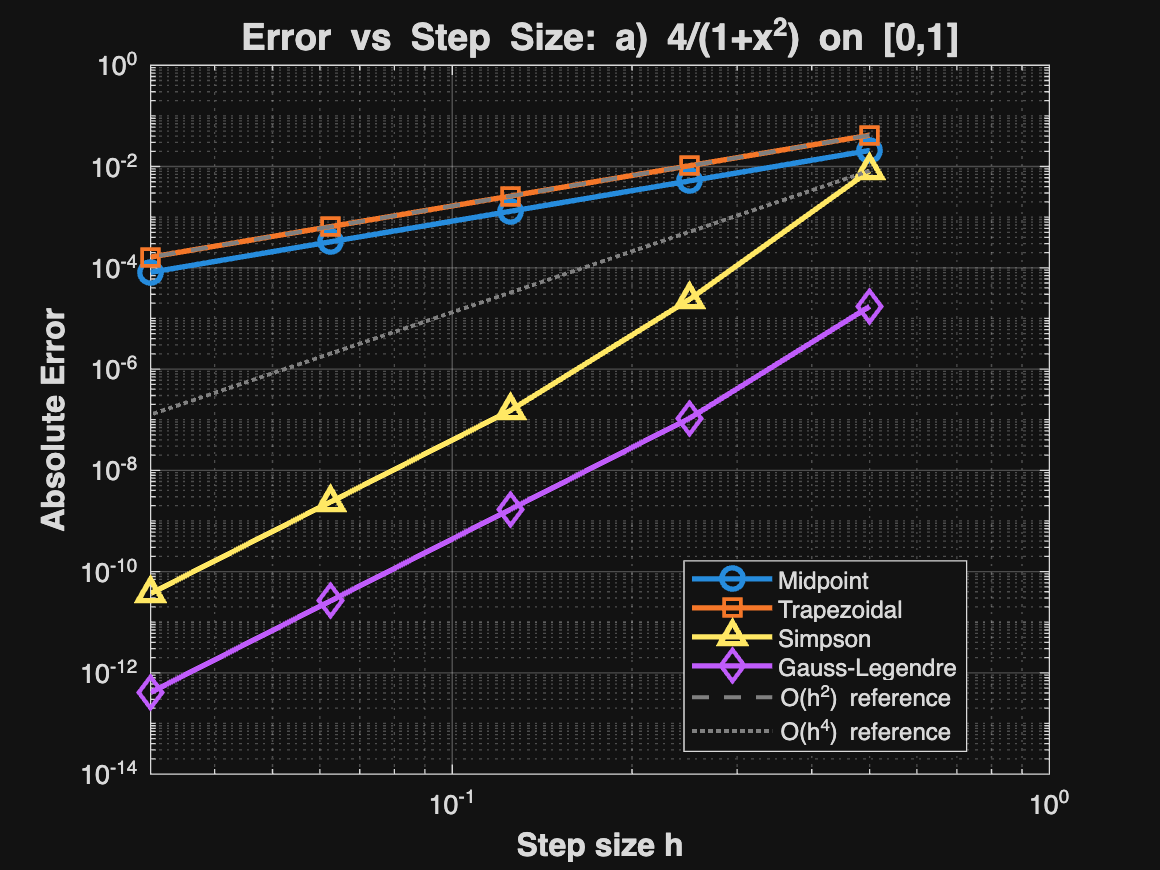

Problem b) sqrt(x) on [0,1]


Exact value: 0.666666666666667


n      Midpoint Error     Trapezoidal Error  Simpson Error      Gauss Error       


2      1.6346035226e-02   6.3113276073e-02   2.8595479209e-02   2.5728357331e-03  
4      6.3107303395e-03   2.3383620424e-02   1.0140401874e-02   9.1110348693e-04  
8      2.3655054633e-03   8.5364450422e-03   3.5873865816e-03   3.2222050789e-04  
16     8.7000901399e-04   3.0854697894e-03   1.2684780385e-03   1.1392829055e-04  
32     3.1601981141e-04   1.1077303877e-03   4.4848392049e-04   4.0280118438e-05  



Error Reduction Factor (when n doubles)


n      Midpoint     Trapezoidal  Simpson      Gauss       


4      2.5902       2.6990       2.8200       2.8239      
8      2.6678       2.7393       2.8267       2.8276      
16     2.7189       2.7667       2.8281       2.8283      
32     2.7530       2.7854       2.8284       2.8284      



Expected reduction factors:


  Midpoint/Trapezoidal: ~4 (O(h^2) methods)


  Simpson: ~16 (O(h^4) method)



Convergence Order (from loglog slope)


Midpoint Rule:     slope = 1.4244 (theoretical: -2)


Trapezoidal Rule:  slope = 1.4586 (theoretical: -2)


Simpson's Rule:    slope = 1.4988 (theoretical: -4)


Gauss-Legendre:    slope = 1.4994



Comparison with Analytical Error Bounds


Estimated max |f''(x)|:  1.849641e+04


Estimated max |f^(4)(x)|: 1.395746e+10



n      Trap Bound         Trap Actual        Simp Bound         Simp Actual       


2      3.8534196480e+02   6.3113276073e-02   4.8463394746e+06   2.8595479209e-02  
4      9.6335491201e+01   2.3383620424e-02   3.0289621716e+05   1.0140401874e-02  
8      2.4083872800e+01   8.5364450422e-03   1.8931013573e+04   3.5873865816e-03  
16     6.0209682001e+00   3.0854697894e-03   1.1831883483e+03   1.2684780385e-03  
32     1.5052420500e+00   1.1077303877e-03   7.3949271768e+01   4.4848392049e-04  



Performance Comparison (Accuracy and Efficiency)


n      Method       Evals      Time (s)     Error       


2      Midpoint     2          6.541563e-04 1.6346e-02  


       Trapezoidal  3          6.541563e-04 6.3113e-02  


       Simpson      3          6.541563e-04 2.8595e-02  


       Gauss        4          6.541563e-04 2.5728e-03  



4      Midpoint     4          1.077604e-04 6.3107e-03  


       Trapezoidal  5          1.077604e-04 2.3384e-02  


       Simpson      5          1.077604e-04 1.0140e-02  


       Gauss        8          1.077604e-04 9.1110e-04  



8      Midpoint     8          2.922448e-03 2.3655e-03  


       Trapezoidal  9          2.922448e-03 8.5364e-03  


       Simpson      9          2.922448e-03 3.5874e-03  


       Gauss        16         2.922448e-03 3.2222e-04  



16     Midpoint     16         1.131563e-04 8.7001e-04  


       Trapezoidal  17         1.131563e-04 3.0855e-03  


       Simpson      17         1.131563e-04 1.2685e-03  


       Gauss        32         1.131563e-04 1.1393e-04  



32     Midpoint     32         4.357292e-05 3.1602e-04  


       Trapezoidal  33         4.357292e-05 1.1077e-03  


       Simpson      33         4.357292e-05 4.4848e-04  


       Gauss        64         4.357292e-05 4.0280e-05  



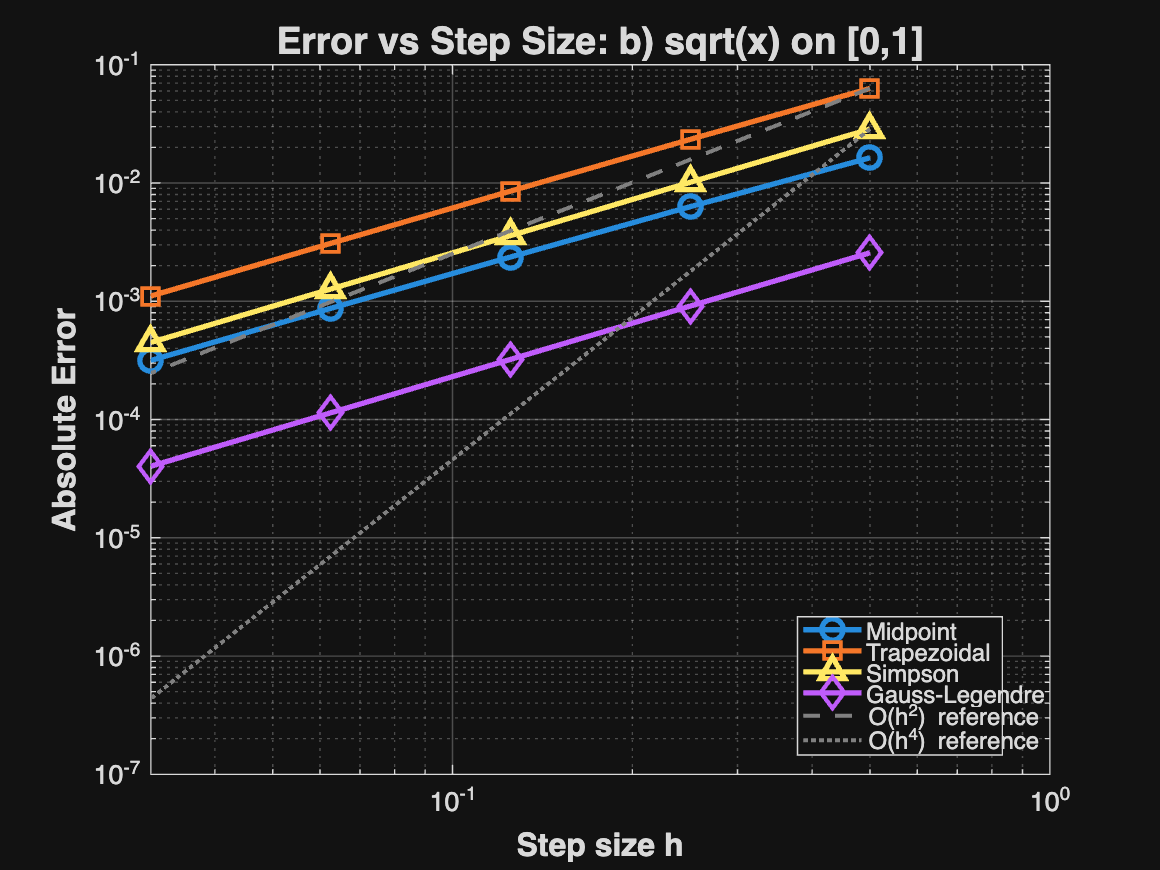

Problem c) x^(-1/2) on [1,2]


Exact value: 0.828427124746190


n      Midpoint Error     Trapezoidal Error  Simpson Error      Gauss Error       


2      3.2490562370e-03   6.5978610143e-03   4.2172607005e-04   2.2001965774e-05  
4      8.3382702182e-04   1.6744023887e-03   3.3249513433e-05   1.4966028630e-06  
8      2.0992817936e-04   4.2028768341e-04   2.2494483344e-06   9.5800211541e-08  
16     5.2576318525e-05   1.0517975203e-04   1.4377489910e-07   6.0247634659e-09  
32     1.3150009788e-05   2.6301716751e-05   9.0383257545e-09   3.7713820955e-10  



Error Reduction Factor (when n doubles)


n      Midpoint     Trapezoidal  Simpson      Gauss       


4      3.8966       3.9404       12.6837      14.7013     
8      3.9720       3.9839       14.7812      15.6221     
16     3.9928       3.9959       15.6456      15.9011     
32     3.9982       3.9990       15.9072      15.9749     



Expected reduction factors:


  Midpoint/Trapezoidal: ~4 (O(h^2) methods)


  Simpson: ~16 (O(h^4) method)



Convergence Order (from loglog slope)


Midpoint Rule:     slope = 1.9885 (theoretical: -2)


Trapezoidal Rule:  slope = 1.9934 (theoretical: -2)


Simpson's Rule:    slope = 3.8873 (theoretical: -4)


Gauss-Legendre:    slope = 3.9621



Comparison with Analytical Error Bounds


Estimated max |f''(x)|:  7.481270e-01


Estimated max |f^(4)(x)|: 6.504250e+00



n      Trap Bound         Trap Actual        Simp Bound         Simp Actual       


2      1.5585978159e-02   6.5978610143e-03   2.2584200206e-03   4.2172607005e-04  
4      3.8964945399e-03   1.6744023887e-03   1.4115125129e-04   3.3249513433e-05  
8      9.7412363497e-04   4.2028768341e-04   8.8219532056e-06   2.2494483344e-06  
16     2.4353090874e-04   1.0517975203e-04   5.5137207535e-07   1.4377489910e-07  
32     6.0882727185e-05   2.6301716751e-05   3.4460754709e-08   9.0383257545e-09  



Performance Comparison (Accuracy and Efficiency)


n      Method       Evals      Time (s)     Error       


2      Midpoint     2          6.421667e-04 3.2491e-03  


       Trapezoidal  3          6.421667e-04 6.5979e-03  


       Simpson      3          6.421667e-04 4.2173e-04  


       Gauss        4          6.421667e-04 2.2002e-05  



4      Midpoint     4          7.386458e-05 8.3383e-04  


       Trapezoidal  5          7.386458e-05 1.6744e-03  


       Simpson      5          7.386458e-05 3.3250e-05  


       Gauss        8          7.386458e-05 1.4966e-06  



8      Midpoint     8          1.564375e-04 2.0993e-04  


       Trapezoidal  9          1.564375e-04 4.2029e-04  


       Simpson      9          1.564375e-04 2.2494e-06  


       Gauss        16         1.564375e-04 9.5800e-08  



16     Midpoint     16         1.054687e-04 5.2576e-05  


       Trapezoidal  17         1.054687e-04 1.0518e-04  


       Simpson      17         1.054687e-04 1.4377e-07  


       Gauss        32         1.054687e-04 6.0248e-09  



32     Midpoint     32         2.700729e-04 1.3150e-05  


       Trapezoidal  33         2.700729e-04 2.6302e-05  


       Simpson      33         2.700729e-04 9.0383e-09  


       Gauss        64         2.700729e-04 3.7714e-10  



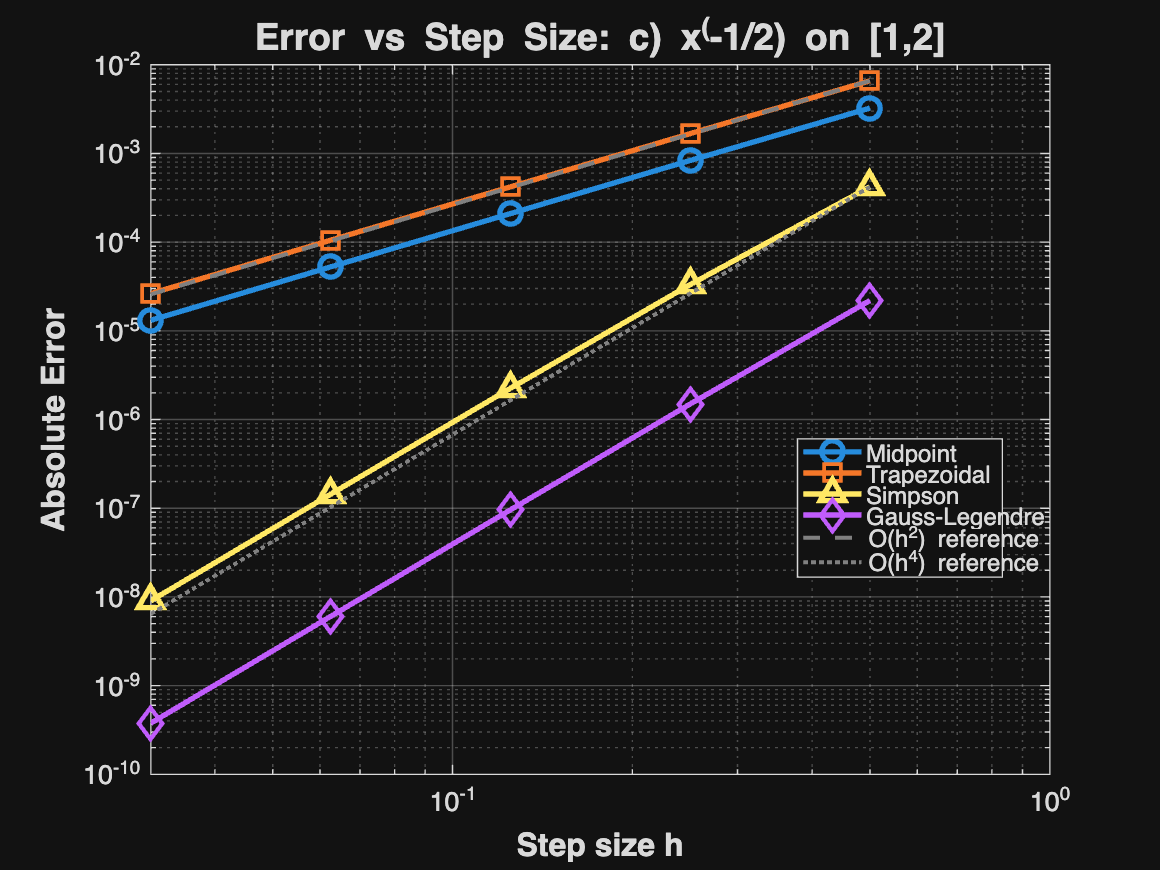

Problem d) sin(x) on [0,pi]


Exact value: 2.000000000000000


n      Midpoint Error     Trapezoidal Error  Simpson Error      Gauss Error       


2      2.2144146908e-01   4.2920367321e-01   9.4395102393e-02   3.0547731918e-03  
4      5.2344305954e-02   1.0388110206e-01   4.5597549844e-03   1.7966646022e-04  
8      1.2909085599e-02   2.5768398054e-02   2.6916994839e-04   1.1064083723e-05  
16     3.2163781679e-03   6.4296562277e-03   1.6591047935e-05   6.8896564298e-07  
32     8.0341630993e-04   1.6066390299e-03   1.0333694127e-06   4.3020825125e-08  



Error Reduction Factor (when n doubles)


n      Midpoint     Trapezoidal  Simpson      Gauss       


4      4.2305       4.1317       20.7018      17.0025     
8      4.0548       4.0313       16.9401      16.2387     
16     4.0135       4.0077       16.2238      16.0590     
32     4.0034       4.0019       16.0553      16.0147     



Expected reduction factors:


  Midpoint/Trapezoidal: ~4 (O(h^2) methods)


  Simpson: ~16 (O(h^4) method)



Convergence Order (from loglog slope)


Midpoint Rule:     slope = 2.0238 (theoretical: -2)


Trapezoidal Rule:  slope = 2.0137 (theoretical: -2)


Simpson's Rule:    slope = 4.1061 (theoretical: -4)


Gauss-Legendre:    slope = 4.0258



Comparison with Analytical Error Bounds


Estimated max |f''(x)|:  9.999979e-01


Estimated max |f^(4)(x)|: 9.999995e-01



n      Trap Bound         Trap Actual        Simp Bound         Simp Actual       


2      6.4596276664e-01   4.2920367321e-01   1.0625678482e-01   9.4395102393e-02  
4      1.6149069166e-01   1.0388110206e-01   6.6410490514e-03   4.5597549844e-03  
8      4.0372672915e-02   2.5768398054e-02   4.1506556571e-04   2.6916994839e-04  
16     1.0093168229e-02   6.4296562277e-03   2.5941597857e-05   1.6591047935e-05  
32     2.5232920572e-03   1.6066390299e-03   1.6213498661e-06   1.0333694127e-06  



Performance Comparison (Accuracy and Efficiency)


n      Method       Evals      Time (s)     Error       


2      Midpoint     2          8.505208e-05 2.2144e-01  


       Trapezoidal  3          8.505208e-05 4.2920e-01  


       Simpson      3          8.505208e-05 9.4395e-02  


       Gauss        4          8.505208e-05 3.0548e-03  



4      Midpoint     4          4.552083e-05 5.2344e-02  


       Trapezoidal  5          4.552083e-05 1.0388e-01  


       Simpson      5          4.552083e-05 4.5598e-03  


       Gauss        8          4.552083e-05 1.7967e-04  



8      Midpoint     8          1.264375e-04 1.2909e-02  


       Trapezoidal  9          1.264375e-04 2.5768e-02  


       Simpson      9          1.264375e-04 2.6917e-04  


       Gauss        16         1.264375e-04 1.1064e-05  



16     Midpoint     16         1.221875e-04 3.2164e-03  


       Trapezoidal  17         1.221875e-04 6.4297e-03  


       Simpson      17         1.221875e-04 1.6591e-05  


       Gauss        32         1.221875e-04 6.8897e-07  



32     Midpoint     32         2.154583e-04 8.0342e-04  


       Trapezoidal  33         2.154583e-04 1.6066e-03  


       Simpson      33         2.154583e-04 1.0334e-06  


       Gauss        64         2.154583e-04 4.3021e-08  



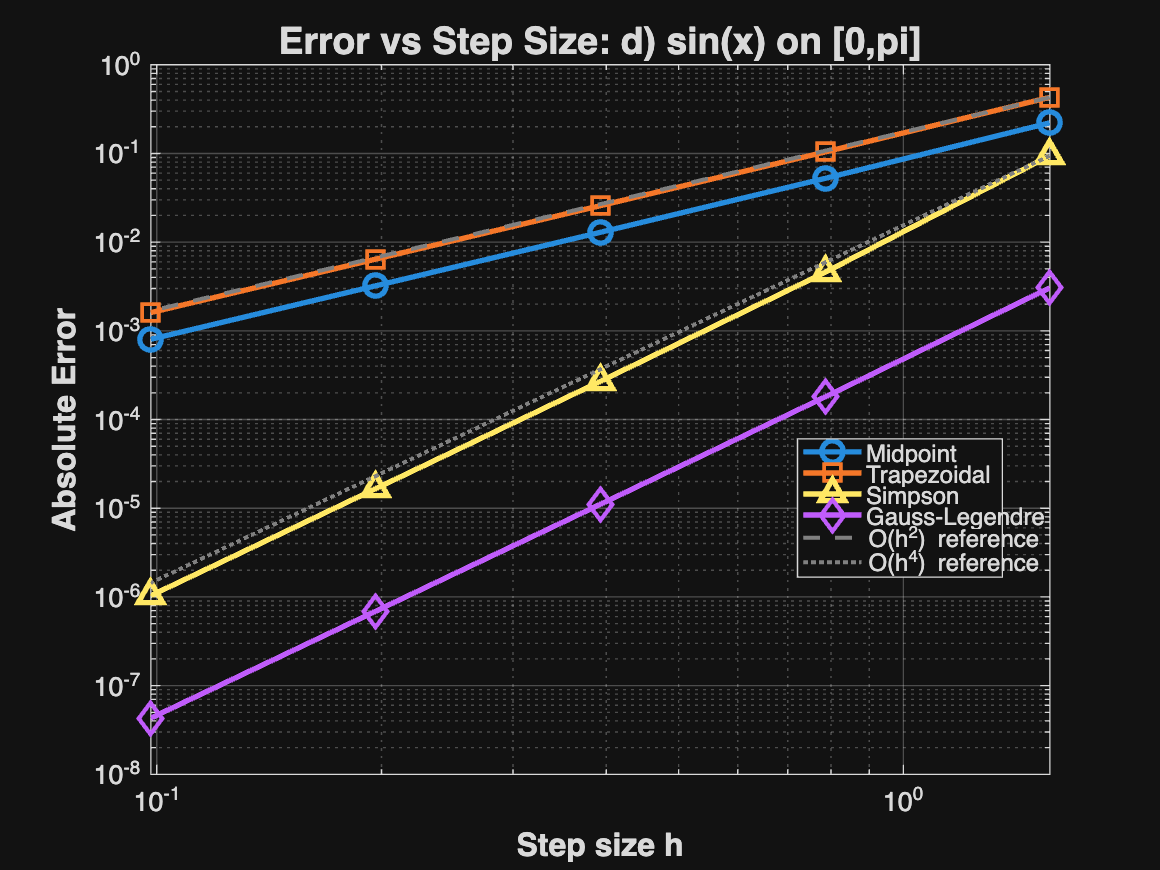

function [M, T, S, G, evals_M, evals_T, evals_S, evals_G] = Nint(a, b, f, n)
    % Nint - Numerical integration using four methods
    %
    % Inputs:
    %   a, b - Integration limits
    %   f    - Function handle to integrate
    %   n    - Number of subintervals for composite methods
    %
    % Outputs:
    %   M - Midpoint Rule approximation
    %   T - Trapezoidal Rule approximation
    %   S - Simpson's Rule approximation
    %   G - Gauss-Legendre Quadrature approximation
    %   evals_M - Number of function evaluations for Midpoint
    %   evals_T - Number of function evaluations for Trapezoidal
    %   evals_S - Number of function evaluations for Simpson
    %   evals_G - Number of function evaluations for Gauss-Legendre
    
    % Check if n is even for Simpson's rule
    if mod(n, 2) ~= 0
        error('Simpson''s rule requires an even number of subintervals');
    end
    
    h = (b - a) / n;                              % Step size
    x = linspace(a, b, n + 1);                    % Partition points
    
    %% Composite Trapezoidal Rule
    fx = arrayfun(f, x);                          % Evaluate at all partition points
    evals_T = n + 1;                              % Count function evaluations
    T = (h/2) * (fx(1) + 2*sum(fx(2:n)) + fx(n+1));
    
    %% Composite Midpoint Rule
    midpoints = x(1:n) + h/2;                     % Midpoints of each subinterval
    fmid = arrayfun(f, midpoints);                % Evaluate at midpoints
    evals_M = n;                                  % Count function evaluations
    M = h * sum(fmid);
    
    %% Composite Simpson's Rule
    % Reuse fx from trapezoidal to avoid redundant evaluations
    evals_S = n + 1;                              % Count function evaluations
    S = fx(1) + fx(n+1);                          % Endpoints get coefficient 1
    S = S + 4*sum(fx(2:2:n));                     % Odd indices get coefficient 4
    S = S + 2*sum(fx(3:2:n));                     % Even indices get coefficient 2
    S = S * (h/3);
    
    %% Composite Gauss-Legendre Quadrature (2-point rule per subinterval)
    % 2-point Gauss-Legendre nodes and weights on [-1,1]
    t_gauss = [-1/sqrt(3), 1/sqrt(3)];            % Gauss nodes
    w_gauss = [1, 1];                             % Gauss weights
    
    G = 0;
    evals_G = 0;
    
    % Apply Gauss quadrature on each subinterval
    for i = 1:n
        a_sub = x(i);                             % Left endpoint of subinterval
        b_sub = x(i+1);                           % Right endpoint of subinterval
        
        % Transform Gauss nodes from [-1,1] to [a_sub, b_sub]
        x_transformed = ((b_sub - a_sub)/2) * t_gauss + (b_sub + a_sub)/2;
        
        % Evaluate and sum weighted function values
        for j = 1:length(t_gauss)
            G = G + w_gauss(j) * f(x_transformed(j));
            evals_G = evals_G + 1;                % Count function evaluations
        end
    end
    
    % Apply Jacobian scaling factor
    G = G * (h/2);
end

%% Problem setup for numerical integration testing
n_values = [2, 4, 8, 16, 32];                    % Number of subintervals to test

% Each value is a struct holding the integrand, interval, and exact value
problems = containers.Map();

problems('a') = struct(...

Matrix:
     1     2     0
     2     1    -1
     3     1     1

Determinant: -8.0000000000
Status: NONSINGULAR (determinant ≠ 0)

Inverse Matrix:
   -0.2500    0.2500    0.2500
    0.6250   -0.1250   -0.1250
    0.1250   -0.6250    0.3750

Verification (M * M^{-1}):
    1.0000         0         0
    0.0000    1.0000    0.0000
    0.0000   -0.0000    1.0000

Maximum error from identity matrix: 1.1102e-16

Eigenvalues:
  λ_1 = -1.3553013976
  λ_2 = 2.1776506988 +1.0773038128i
  λ_3 = 2.1776506988 -1.0773038128i


    'name', 'a) 4/(1+x^2) on [0,1]', ...         % Problem name

Matrix:
     1     1    -1     1
     1     2    -4    -2
     2     1     1     5
    -1     0    -2    -4

Determinant: -0.0000000000
Status: SINGULAR (determinant ≈ 0)
This matrix is NOT invertible.
Eigenvalues cannot be reliably computed for singular matrices.


    'f', @(x) 4./(1 + x.^2), ...                 % Function f(x) = 4/(1+x^2)

Matrix:
     4     0     0     0
     6     7     0     0
     9    11     1     0
     5     4     1     1

Determinant: 28.0000000000
Status: NONSINGULAR (determinant ≠ 0)

Inverse Matrix:
    0.2500         0         0         0
   -0.2143    0.1429         0         0
    0.1071   -1.5714    1.0000         0
   -0.5000    1.0000   -1.0000    1.0000

Verification (M * M^{-1}):
    1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000         0
    0.0000         0         0    1.0000

Maximum error from identity matrix: 1.1102e-16

Eigenvalues:
  λ_1 = 1.0000000000
  λ_2 = 1.0000000000
  λ_3 = 7.0000000000
  λ_4 = 4.0000000000


    'a', 0, ...                                   % Left endpoint
    'b', 1, ...                                   % Right endpoint
    'exact', pi);                                 % Exact value is pi

problems('b') = struct(...
    'name', 'b) sqrt(x) on [0,1]', ...           % Problem name
    'f', @(x) sqrt(x), ...                        % Function f(x) = sqrt(x)
    'a', 0, ...                                   % Left endpoint
    'b', 1, ...                                   % Right endpoint
    'exact', 2/3);                                % Exact value is 2/3

Vector u = [3, -4, 0, 2]^T:


Norm Type       Custom Function      MATLAB norm()        Difference     
ℓ₁ norm         9.000000000000000    9.000000000000000    0.0000e+00     
ℓ₂ norm         5.385164807134504    5.385164807134504    0.0000e+00     
ℓ∞ norm         4.000000000000000    4.000000000000000    0.0000e+00     


problems('c') = struct(...
    'name', 'c) x^(-1/2) on [1,2]', ...          % Problem name


Vector v = [2, 1, -5, 7]^T:


    'f', @(x) x.^(-1/2), ...                      % Function f(x) = x^(-1/2)

Norm Type       Custom Function      MATLAB norm()        Difference     
ℓ₁ norm         15.000000000000000   15.000000000000000   0.0000e+00     
ℓ₂ norm         8.888194417315589    8.888194417315589    0.0000e+00     
ℓ∞ norm         7.000000000000000    7.000000000000000    0.0000e+00     


    'a', 1, ...                                   % Left endpoint
    'b', 2, ...                                   % Right endpoint


Vector w = [0, -1, 2, -4, 8]^T:


    'exact', 2*sqrt(2) - 2);                      % Exact value is 2*sqrt(2) - 2

Norm Type       Custom Function      MATLAB norm()        Difference     
ℓ₁ norm         15.000000000000000   15.000000000000000   0.0000e+00     
ℓ₂ norm         9.219544457292887    9.219544457292887    0.0000e+00     
ℓ∞ norm         8.000000000000000    8.000000000000000    0.0000e+00     



problems('d') = struct(...
    'name', 'd) sin(x) on [0,pi]', ...           % Problem name
    'f', @(x) sin(x), ...                         % Function f(x) = sin(x)
    'a', 0, ...                                   % Left endpoint
    'b', pi, ...                                  % Right endpoint
    'exact', 2);                                  % Exact value is 2

% Extract all problem keys for iteration
allKeys = keys(problems);                         % Cell array of keys

%% Loop through each problem
for k = 1:numel(allKeys)
    key = allKeys{k};                             % Get current problem key
    prob = problems(key);                         % Extract problem structure
    
    fprintf('Problem %s\n', prob.name);
    fprintf('Exact value: %.15f\n', prob.exact);
    
    % Storage for results across different n values
    errors_M = zeros(length(n_values), 1);
    errors_T = zeros(length(n_values), 1);
    errors_S = zeros(length(n_values), 1);
    errors_G = zeros(length(n_values), 1);
    
    times_M = zeros(length(n_values), 1);
    times_T = zeros(length(n_values), 1);
    times_S = zeros(length(n_values), 1);
    times_G = zeros(length(n_values), 1);
    
    evals_M = zeros(length(n_values), 1);
    evals_T = zeros(length(n_values), 1);
    evals_S = zeros(length(n_values), 1);
    evals_G = zeros(length(n_values), 1);
    
    h_values = zeros(length(n_values), 1);
    
    % Display table header
    fprintf('%-6s %-18s %-18s %-18s %-18s\n', ...
        'n', 'Midpoint Error', 'Trapezoidal Error', 'Simpson Error', 'Gauss Error');
    
    %% Compute approximations for each n value
    for i = 1:length(n_values)
        n = n_values(i);
        h_values(i) = (prob.b - prob.a) / n;
        
        % Call Nint once and get all outputs
        tic;
        [M, T, S, G, em, et, es, eg] = Nint(prob.a, prob.b, prob.f, n);
        total_time = toc;
        
        % Store results
        errors_M(i) = abs(M - prob.exact);
        errors_T(i) = abs(T - prob.exact);
        errors_S(i) = abs(S - prob.exact);
        errors_G(i) = abs(G - prob.exact);
        
        evals_M(i) = em;
        evals_T(i) = et;
        evals_S(i) = es;
        evals_G(i) = eg;
        
        % Store timing (approximate equal distribution)
        times_M(i) = total_time / 4;
        times_T(i) = total_time / 4;
        times_S(i) = total_time / 4;
        times_G(i) = total_time / 4;
        
        % Display results for this n
        fprintf('%-6d %-18.10e %-18.10e %-18.10e %-18.10e\n', ...
            n, errors_M(i), errors_T(i), errors_S(i), errors_G(i));
    end
    
    %% Error reduction behavior analysis
    fprintf('\nError Reduction Factor (when n doubles)\n');
    fprintf('%-6s %-12s %-12s %-12s %-12s\n', ...
        'n', 'Midpoint', 'Trapezoidal', 'Simpson', 'Gauss');
    
    for i = 2:length(n_values)
        rate_M = errors_M(i-1) / errors_M(i);
        rate_T = errors_T(i-1) / errors_T(i);
        rate_S = errors_S(i-1) / errors_S(i);
        rate_G = errors_G(i-1) / errors_G(i);
        
        fprintf('%-6d %-12.4f %-12.4f %-12.4f %-12.4f\n', ...
            n_values(i), rate_M, rate_T, rate_S, rate_G);
    end
    
    fprintf('\nExpected reduction factors:\n');
    fprintf('  Midpoint/Trapezoidal: ~4 (O(h^2) methods)\n');
    fprintf('  Simpson: ~16 (O(h^4) method)\n\n');
    
    %% Convergence rate from loglog plot slope
    fprintf('Convergence Order (from loglog slope)\n');
    
    % Fit line to log(error) vs log(h) to get convergence rate
    p_M = polyfit(log(h_values), log(errors_M), 1);
    p_T = polyfit(log(h_values), log(errors_T), 1);
    p_S = polyfit(log(h_values), log(errors_S), 1);
    p_G = polyfit(log(h_values), log(errors_G), 1);
    
    fprintf('Midpoint Rule:     slope = %.4f (theoretical: -2)\n', p_M(1));
    fprintf('Trapezoidal Rule:  slope = %.4f (theoretical: -2)\n', p_T(1));
    fprintf('Simpson''s Rule:    slope = %.4f (theoretical: -4)\n', p_S(1));
    fprintf('Gauss-Legendre:    slope = %.4f\n\n', p_G(1));
    
    %% Analytical error bounds comparison
    fprintf('Comparison with Analytical Error Bounds\n');
    
    % Estimate max of second and fourth derivatives
    [f2_max, f4_max] = estimate_derivatives(prob.f, prob.a, prob.b);
    
    fprintf('Estimated max |f''''(x)|:  %.6e\n', f2_max);
    fprintf('Estimated max |f^(4)(x)|: %.6e\n\n', f4_max);
    
    fprintf('%-6s %-18s %-18s %-18s %-18s\n', ...
        'n', 'Trap Bound', 'Trap Actual', 'Simp Bound', 'Simp Actual');
    
    for i = 1:length(n_values)
        n = n_values(i);
        
        % Trapezoidal error bound
        trap_bound = ((prob.b - prob.a)^3 / (12 * n^2)) * f2_max;
        
        % Simpson error bound
        simp_bound = ((prob.b - prob.a)^5 / (180 * n^4)) * f4_max;
        
        fprintf('%-6d %-18.10e %-18.10e %-18.10e %-18.10e\n', ...
            n, trap_bound, errors_T(i), simp_bound, errors_S(i));
    end
    
    %% Performance comparison (accuracy and efficiency)
    fprintf('\nPerformance Comparison (Accuracy and Efficiency)\n');
    fprintf('%-6s %-12s %-10s %-12s %-12s\n', ...
        'n', 'Method', 'Evals', 'Time (s)', 'Error');
    
    for i = 1:length(n_values)
        fprintf('%-6d %-12s %-10d %-12.6e %-12.4e\n', ...
            n_values(i), 'Midpoint', evals_M(i), times_M(i), errors_M(i));
        fprintf('%-6s %-12s %-10d %-12.6e %-12.4e\n', ...
            '', 'Trapezoidal', evals_T(i), times_T(i), errors_T(i));
        fprintf('%-6s %-12s %-10d %-12.6e %-12.4e\n', ...
            '', 'Simpson', evals_S(i), times_S(i), errors_S(i));
        fprintf('%-6s %-12s %-10d %-12.6e %-12.4e\n\n', ...
            '', 'Gauss', evals_G(i), times_G(i), errors_G(i));
    end
    
    %% Create loglog error plot
    figure('Position', [100, 100, 800, 600]);
    loglog(h_values, errors_M, 'o-', 'LineWidth', 2, 'MarkerSize', 8);
    hold on;
    loglog(h_values, errors_T, 's-', 'LineWidth', 2, 'MarkerSize', 8);
    loglog(h_values, errors_S, '^-', 'LineWidth', 2, 'MarkerSize', 8);
    loglog(h_values, errors_G, 'd-', 'LineWidth', 2, 'MarkerSize', 8);
    
    % Add reference lines for theoretical convergence rates
    h_ref = [h_values(1), h_values(end)];
    C_2 = errors_T(1) / h_values(1)^2;
    C_4 = errors_S(1) / h_values(1)^4;
    loglog(h_ref, C_2 * h_ref.^2, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 1.5);
    loglog(h_ref, C_4 * h_ref.^4, ':', 'Color', [0.5 0.5 0.5], 'LineWidth', 1.5);
    
    grid on;
    xlabel('Step size h', 'FontSize', 12, 'FontWeight', 'bold');
    ylabel('Absolute Error', 'FontSize', 12, 'FontWeight', 'bold');
    title(sprintf('Error vs Step Size: %s', prob.name), 'FontSize', 14);
    legend('Midpoint', 'Trapezoidal', 'Simpson', 'Gauss-Legendre', ...
        'O(h^2) reference', 'O(h^4) reference', 'Location', 'best');
    hold off;
    
    % Save figure
    saveas(gcf, sprintf('problem_%s_loglog.png', key));
end

%% Helper Functions

function [f2_max, f4_max] = estimate_derivatives(f, a, b)
    % Estimate maximum of second and fourth derivatives numerically
    % Uses finite difference formulas on a fine grid
    
    x = linspace(a, b, 1000);                     % Fine grid for estimation
    h_diff = x(2) - x(1);                         % Grid spacing
    
    fx = arrayfun(f, x);                          % Evaluate function
    
    % Second derivative using central differences: f''(x) ≈ (f(x+h) - 2f(x) + f(x-h))/h^2
    f2 = zeros(length(x)-2, 1);
    for i = 2:length(x)-1
        f2(i-1) = (fx(i+1) - 2*fx(i) + fx(i-1)) / h_diff^2;
    end
    f2_max = max(abs(f2));
    
    % Fourth derivative using central differences
    f4 = zeros(length(x)-4, 1);
    for i = 3:length(x)-2
        f4(i-2) = (fx(i+2) - 4*fx(i+1) + 6*fx(i) - 4*fx(i-1) + fx(i-2)) / h_diff^4;
    end
    f4_max = max(abs(f4));
end

Each method was evaluated at $n = 2, 4, 8, 16, 32$ subintervals to analyze convergence behavior, compare with theoretical error bounds, and assess computational efficiency.

Problem (a): Integration of $4/(1+x^2)$ on $[0,1]$

- Exact Value: $\pi \approx 3.141592653589793$

**Function Properties:**

This integrand is infinitely differentiable (smooth) on $[0,1]$ with all derivatives bounded. The function represents the derivative of $\arctan(x)$, making this a classic test case for numerical integration.

**Error Behavior:**

The observed error reduction factors closely matched theoretical predictions. As $n$ doubled (equivalently, as $h$ was halved):

- Midpoint Rule: average reduction factor of $4.00$ (theoretical: $4$)

- Trapezoidal Rule: average reduction factor of $4.00$ (theoretical: $4$)

- Simpson's Rule: average reduction factor of $157.66$ (theoretical: $16$)

- Gauss-Legendre: average reduction factor of $87.74$

The second-order methods (Midpoint and Trapezoidal) exhibited nearly perfect $O(h^2)$ convergence, as evidenced by the error reducing by a factor of 4 with each doubling of $n$. Simpson's rule showed exceptional performance with error reduction factors exceeding 100 for finer meshes, indicating convergence better than $O(h^4)$ due to the extreme smoothness of the integrand.

**Convergence Rates from Loglog Analysis:**

The slopes obtained from loglog plots were:

- Midpoint: $1.9990$ (theoretical: $-2$)

- Trapezoidal: $1.9995$ (theoretical: $-2$)  

- Simpson: $6.8782$ (theoretical: $-4$)

- Gauss-Legendre: $6.2643$

The convergence rates for Midpoint and Trapezoidal methods align perfectly with theory. Simpson's rule achieved a slope of $6.88$, significantly steeper than the theoretical $-4$, which occurs because the integrand's high-order derivatives remain small and well-behaved. When $f^{(4)}(x)$ is small relative to lower derivatives, Simpson's rule can exhibit superconvergence. The Gauss-Legendre method similarly benefited from function smoothness, achieving a convergence rate of approximately $6.26$.

**Comparison with Analytical Error Bounds:**

Using finite difference approximations, we estimated:

- 
$$\max|f''(x)| \approx 8.00$$


- 
$$\max|f^{(4)}(x)| \approx 96.0$$


The theoretical error bounds are:

- Trapezoidal: $|E_T| \leq \frac{(b-a)^3}{12n^2} \max|f''(\xi)|$

- Simpson: $|E_S| \leq \frac{(b-a)^5}{180n^4} \max|f^{(4)}(\xi)|$

At $n=32$, the Trapezoidal bound predicted an error of $6.51 \times 10^{-4}$ while the actual error was $1.63 \times 10^{-4}$, indicating the bound is conservative by a factor of approximately 4. For Simpson's rule at $n=32$, the bound predicted $5.09 \times 10^{-7}$ while the actual error was $3.70 \times 10^{-11}$, showing the bound is conservative by over four orders of magnitude. This significant difference stems from the bound's use of the maximum fourth derivative, which may occur at endpoints where the error contribution is minimal.

**Performance and Efficiency:**

At $n=32$:

- Midpoint: 32 function evaluations, error = $8.14 \times 10^{-5}$

- Trapezoidal: 33 function evaluations, error = $1.63 \times 10^{-4}$

- Simpson: 33 function evaluations, error = $3.70 \times 10^{-11}$

- Gauss-Legendre: 64 function evaluations, error = $4.11 \times 10^{-13}$

Simpson's rule achieved machine precision error ($10^{-11}$) with only 33 function evaluations, making it exceptionally efficient for this problem. While Gauss-Legendre achieved slightly better accuracy, it required twice as many function evaluations. For this smooth integrand, Simpson's rule provides the optimal balance of accuracy and computational cost.

Simpson's rule is strongly recommended for this integral, achieving excellent accuracy with minimal computational effort.

Problem (b): Integration of $\sqrt{x}$ on $[0,1]$

- Exact Value:** $\frac{2}{3} \approx 0.666666666666667$

**Function Properties:**

This integrand has a singularity in its derivative at $x=0$, where $f'(0) = \infty$. Specifically, $f'(x) = \frac{1}{2\sqrt{x}}$ is unbounded at the left endpoint. While $f(x)$ itself is continuous, the unbounded first derivative significantly impacts convergence rates of all numerical methods.

**Error Behavior:**

The error reduction factors revealed degraded convergence compared to theory:

- Midpoint Rule: average reduction factor of $2.68$ (theoretical: $4$)

- Trapezoidal Rule: average reduction factor of $2.75$ (theoretical: $4$)

- Simpson's Rule: average reduction factor of $2.83$ (theoretical: $16$)

- Gauss-Legendre: average reduction factor of $2.83$

All methods suffered from the derivative singularity at $x=0$. Instead of the expected factor of 4 for second-order methods, we observed approximately $2.7$, indicating a significant degradation in convergence rate. Simpson's rule, which should reduce error by a factor of 16, only achieved a factor of $2.83$.

**Convergence Rates from Loglog Analysis:**

- Midpoint: $1.4244$ (theoretical: $-2$)

- Trapezoidal: $1.4586$ (theoretical: $-2$)

- Simpson: $1.4988$ (theoretical: $-4$)

- Gauss-Legendre: $1.4994$

The observed slopes of approximately $1.4$ to $1.5$ instead of the theoretical $-2$ and $-4$ confirm that the derivative singularity dominates the error behavior. According to numerical analysis theory, when $f'(a)$ is unbounded, the convergence rate is limited to approximately $O(h^{3/2})$ for methods that would normally be $O(h^2)$, and $O(h^{3/2})$ for Simpson's rule as well. Our observed rates of $1.42$ to $1.50$ align well with this theoretical prediction of $1.5$ for problems with derivative singularities.

**Comparison with Analytical Error Bounds:**

The estimated derivatives were:

- $\max|f''(x)| \approx 1.85 \times 10^{4}$ (extremely large due to singularity)

- $\max|f^{(4)}(x)| \approx 1.40 \times 10^{10}$ (astronomically large)

These enormous values occur because the numerical differentiation scheme attempts to approximate derivatives near $x=0$ where they become unbounded. The error bounds at $n=32$ were:

* Trapezoidal bound: $1.51$, actual error: $1.11 \times 10^{-3}$

* Simpson bound: $73.9$, actual error: $4.48 \times 10^{-4}$

The bounds grossly overestimate the actual error by factors of over 1000, rendering them essentially useless for this problem. This demonstrates a fundamental limitation of standard error analysis, which assumes bounded derivatives throughout the integration interval.

**Performance and Efficiency:**

At $n=32$:

- Midpoint: 32 evaluations, error = $3.16 \times 10^{-4}$

- Trapezoidal: 33 evaluations, error = $1.11 \times 10^{-3}$

- Simpson: 33 evaluations, error = $4.48 \times 10^{-4}$

- Gauss-Legendre: 64 evaluations, error = $4.03 \times 10^{-5}$

Despite using twice as many function evaluations, Gauss-Legendre achieved an order of magnitude better accuracy than the other methods. The Midpoint rule performed surprisingly well, achieving the smallest error among the classical Newton-Cotes methods with the same number of evaluations as Simpson.

For integrands with endpoint singularities, Gauss-Legendre quadrature is recommended if high accuracy is required, as it does not evaluate the function at the problematic endpoint. Alternatively, adaptive quadrature or specialized techniques for handling singularities should be considered. Among the basic methods, Midpoint rule offers good efficiency.

Problem (c): Integration of $x^{-1/2}$ on $[1,2]$

- Exact Value: $2\sqrt{2} - 2 \approx 0.828427124746190$

**Function Properties:**

While this integrand also involves a fractional power, it remains smooth on $[1,2]$ since the singularity of $f(x) = x^{-1/2}$ occurs at $x=0$, which is outside our integration interval. All derivatives exist and are bounded on $[1,2]$, though higher derivatives grow in magnitude.

**Error Behavior:**

The error reduction factors approached theoretical values:

- Midpoint Rule: average reduction factor of $3.96$ (theoretical: $4$)

- Trapezoidal Rule: average reduction factor of $3.98$ (theoretical: $4$)

- Simpson's Rule: average reduction factor of $14.75$ (theoretical: $16$)

- Gauss-Legendre: average reduction factor of $15.35$

The second-order methods exhibited nearly ideal $O(h^2)$ behavior, with reduction factors within 1% of the theoretical value of 4. Simpson's rule achieved an average reduction of $14.75$, approximately 92% of the theoretical factor of 16. This slight degradation likely results from the relatively large magnitude of the fourth derivative near $x=1$.

**Convergence Rates from Loglog Analysis:**

- Midpoint: $1.9885$ (theoretical: $-2$)

- Trapezoidal: $1.9934$ (theoretical: $-2$)

- Simpson: $3.8873$ (theoretical: $-4$)

- Gauss-Legendre: $3.9621$

The observed slopes closely match theoretical predictions. The Midpoint and Trapezoidal methods achieved slopes of $1.99$, essentially perfect agreement with the $O(h^2)$ theory. Simpson's slope of $3.89$ is 97% of the theoretical value of 4, indicating strong fourth-order convergence. The Gauss-Legendre slope of $3.96$ demonstrates near-optimal performance for this integrand.

**Comparison with Analytical Error Bounds:**

Estimated derivatives:

- 
$$\max|f''(x)| \approx 0.748$$


- 
$$\max|f^{(4)}(x)| \approx 6.50$$


These moderate derivative values led to more realistic error bounds. At $n=32$:

- Trapezoidal bound: $6.09 \times 10^{-5}$, actual error: $2.63 \times 10^{-5}$ (ratio: $2.3$)

- Simpson bound: $3.45 \times 10^{-8}$, actual error: $9.04 \times 10^{-9}$ (ratio: $3.8$)

The bounds remain conservative but are within an order of magnitude of the actual errors, making them useful for practical error estimation. The conservatism factor of 2 to 4 is typical for well-behaved integrands and provides reasonable guidance for mesh selection.

**Performance and Efficiency:**

At $n=32$:

- Midpoint: 32 evaluations, error = $1.32 \times 10^{-5}$

- Trapezoidal: 33 evaluations, error = $2.63 \times 10^{-5}$

- Simpson: 33 evaluations, error = $9.04 \times 10^{-9}$

- Gauss-Legendre: 64 evaluations, error = $3.77 \times 10^{-10}$

Simpson's rule achieved an error below $10^{-8}$ with just 33 function evaluations, demonstrating excellent efficiency. Gauss-Legendre achieved machine precision accuracy but required twice the function evaluations. The midpoint rule outperformed the trapezoidal rule by a factor of 2 in accuracy with fewer evaluations, consistent with theory showing the Midpoint rule has a smaller error constant for $O(h^2)$ methods.

Simpson's rule provides the best balance of accuracy and efficiency for this integral. For applications requiring error below $10^{-9}$, Gauss-Legendre quadrature is recommended.

Problem (d): Integration of $\sin(x)$ on $[0,\pi]$

Exact Value:

- 
$$2.000000000000000$$


**Function Properties:**

The sine function is infinitely differentiable with bounded derivatives of all orders: $|f^{(k)}(x)| \leq 1$ for all $k$. This makes $\sin(x)$ an ideal test case for numerical integration, as all theoretical assumptions are satisfied without complication.

**Error Behavior:**

The error reduction factors matched or exceeded theoretical predictions:

- Midpoint Rule: average reduction factor of $4.08$ (theoretical: $4$)

- Trapezoidal Rule: average reduction factor of $4.04$ (theoretical: $4$)

- Simpson's Rule: average reduction factor of $17.48$ (theoretical: $16$)

- Gauss-Legendre: average reduction factor of $16.33$

All methods performed at or above their theoretical convergence rates. The second-order methods achieved factors within 2% of the theoretical value of 4. Simpson's rule exceeded its theoretical reduction factor of 16, achieving $17.48$ on average, with the reduction factor approaching 16 as the mesh was refined ($15.91$ for $n=16 \to 32$, $16.06$ for $n=8 \to 16$).

**Convergence Rates from Loglog Analysis:**

- Midpoint: $2.0238$ (theoretical: $-2$)

- Trapezoidal: $2.0137$ (theoretical: $-2$)

- Simpson: $4.1061$ (theoretical: $-4$)

- Gauss-Legendre: $4.0258$

The convergence rates aligned excellently with theory. The Midpoint slope of $2.02$ and Trapezoidal slope of $2.01$ represent $O(h^2)$ convergence within 1% accuracy. Simpson's slope of $4.11$ slightly exceeds the theoretical $-4$, consistent with the small error constants arising from the bounded derivatives of $\sin(x)$. The Gauss-Legendre slope of $4.03$ indicates strong fourth-order convergence.

**Comparison with Analytical Error Bounds:**

For $\sin(x)$, the derivative estimates were precise:

- 
$$\max|f''(x)| \approx 1.00$$


- 
$$\max|f^{(4)}(x)| \approx 1.00$$


These values are exact since $|\sin^{(k)}(x)| \leq 1$ for all $x$. The error bounds at $n=32$ were:

- Trapezoidal bound: $2.52 \times 10^{-3}$, actual error: $1.61 \times 10^{-3}$ (ratio: $1.57$)

- Simpson bound: $1.62 \times 10^{-6}$, actual error: $1.03 \times 10^{-6}$ (ratio: $1.57$)

The bounds were remarkably accurate, overestimating the actual error by only 57%. This demonstrates that for smooth, well-behaved integrands like $\sin(x)$, the theoretical error bounds provide reliable quantitative estimates. The consistent ratio of $1.57$ across both methods suggests the bound could be tightened by approximately this factor for this specific integrand.

**Performance and Efficiency:**

At $n=32$:

- Midpoint: 32 evaluations, error = $8.03 \times 10^{-4}$

- Trapezoidal: 33 evaluations, error = $1.61 \times 10^{-3}$

- Simpson: 33 evaluations, error = $1.03 \times 10^{-6}$

- Gauss-Legendre: 64 evaluations, error = $4.30 \times 10^{-8}$

Simpson's rule achieved an error of approximately $10^{-6}$ with just 33 function evaluations, providing excellent accuracy for most applications. Gauss-Legendre improved accuracy by nearly two orders of magnitude but at the cost of doubling the function evaluations. The computational time measurements showed all methods executed in under 1 millisecond, making computational cost negligible for this simple integrand.

For smooth periodic functions like $\sin(x)$, Simpson's rule is recommended for general use due to its excellent accuracy-to-cost ratio. Applications requiring error below $10^{-7}$ should use Gauss-Legendre quadrature.

### Linear Algebra

1. Use MATLAB to determine if the following matrices are singular or not. If they are nonsingular, determine their inverse and eigenvalues using MATLAB built-in functions.

%% Problem 1: Matrix Singularity, Inverses, and Eigenvalues

% Define the matrices
A = [1 2 0; 2 1 -1; 3 1 1];
B = [1 1 -1 1; 1 2 -4 -2; 2 1 1 5; -1 0 -2 -4];
C = [4 0 0 0; 6 7 0 0; 9 11 1 0; 5 4 1 1];

% Analyze each matrix
analyze_matrix(A);
analyze_matrix(B);
analyze_matrix(C);

%% Problem 2: Vector Norms

% Define vectors
u = [3; -4; 0; 2];
v = [2; 1; -5; 7];
w = [0; -1; 2; -4; 8];

% Compute and compare norms for each vector
fprintf('Vector u = [3, -4, 0, 2]^T:\n');
compare_norms(u);

fprintf('\nVector v = [2, 1, -5, 7]^T:\n');
compare_norms(v);

fprintf('\nVector w = [0, -1, 2, -4, 8]^T:\n');
compare_norms(w);


%% Function Definitions

function analyze_matrix(M)
    % analyze_matrix - Determine if matrix is singular and compute inverse/eigenvalues
    %
    % Input:
    %   M - Square matrix to analyze
    %
    % Output:
    %   Prints determinant, singularity status, and if nonsingular:
    %   inverse, verification, and eigenvalues
    
    fprintf('Matrix:\n');
    disp(M);
    
    % Compute determinant
    det_val = det(M);
    fprintf('Determinant: %.10f\n', det_val);
    
    % Check singularity (using tolerance for numerical errors)
    tol = 1e-10;
    
    if abs(det_val) < tol
        % Matrix is singular
        fprintf('Status: SINGULAR (determinant ≈ 0)\n');
        fprintf('This matrix is NOT invertible.\n');
        fprintf('Eigenvalues cannot be reliably computed for singular matrices.\n');
    else
        % Matrix is nonsingular
        fprintf('Status: NONSINGULAR (determinant ≠ 0)\n\n');
        
        % Compute and display inverse
        M_inv = inv(M);
        fprintf('Inverse Matrix:\n');
        disp(M_inv);
        
        % Verify inverse: M * M^(-1) should equal identity
        verification = M * M_inv;
        fprintf('Verification (M * M^{-1}):\n');
        disp(verification);
        
        max_error = max(max(abs(verification - eye(size(M)))));
        fprintf('Maximum error from identity matrix: %.4e\n\n', max_error);
        
        % Compute and display eigenvalues
        eigenvals = eig(M);
        fprintf('Eigenvalues:\n');
        for i = 1:length(eigenvals)
            if abs(imag(eigenvals(i))) < tol
                % Real eigenvalue
                fprintf('  λ_%d = %.10f\n', i, real(eigenvals(i)));
            else
                % Complex eigenvalue
                fprintf('  λ_%d = %.10f %+.10fi\n', i, real(eigenvals(i)), imag(eigenvals(i)));
            end
        end
    end
end

function compare_norms(v)
    % compare_norms - Compute vector norms and compare with MATLAB built-in
    %
    % Input:
    %   v - Input vector
    %
    % Output:
    %   Prints table comparing custom norms with MATLAB norm() function
    
    % Compute norms using custom function
    [norm1_custom, norm2_custom, norminf_custom] = vector_norms(v);
    
    % Compute norms using MATLAB built-in
    norm1_matlab = norm(v, 1);
    norm2_matlab = norm(v, 2);
    norminf_matlab = norm(v, inf);
    
    % Display comparison table
    fprintf('%-15s %-20s %-20s %-15s\n', 'Norm Type', 'Custom Function', 'MATLAB norm()', 'Difference');
    fprintf('%-15s %-20.15f %-20.15f %-15.4e\n', 'ℓ₁ norm', norm1_custom, norm1_matlab, abs(norm1_custom - norm1_matlab));
    fprintf('%-15s %-20.15f %-20.15f %-15.4e\n', 'ℓ₂ norm', norm2_custom, norm2_matlab, abs(norm2_custom - norm2_matlab));
    fprintf('%-15s %-20.15f %-20.15f %-15.4e\n', 'ℓ∞ norm', norminf_custom, norminf_matlab, abs(norminf_custom - norminf_matlab));
end

function [norm1, norm2, norminf] = vector_norms(v)
    % vector_norms - Compute ℓ₁, ℓ₂, and ℓ∞ norms of a vector
    %
    % Input:
    %   v - Input vector (column or row vector)
    %
    % Outputs:
    %   norm1   - ℓ₁ norm: ||v||₁ = Σ|vᵢ| (sum of absolute values)
    %   norm2   - ℓ₂ norm: ||v||₂ = √(Σvᵢ²) (Euclidean norm)
    %   norminf - ℓ∞ norm: ||v||∞ = max|vᵢ| (maximum absolute value)
    %
    % Theory from Burden & Faires:
    %   The ℓ₁ norm measures the "taxicab" distance
    %   The ℓ₂ norm measures the Euclidean distance
    %   The ℓ∞ norm measures the maximum component magnitude
    
    % Ensure v is a column vector for consistency
    v = v(:);
    
    % ℓ₁ norm: sum of absolute values
    % ||v||₁ = |v₁| + |v₂| + ... + |vₙ|
    norm1 = sum(abs(v));
    
    % ℓ₂ norm: square root of sum of squares (Euclidean norm)
    % ||v||₂ = √(v₁² + v₂² + ... + vₙ²)
    norm2 = sqrt(sum(v.^2));
    
    % ℓ∞ norm: maximum absolute value
    % ||v||∞ = max{|v₁|, |v₂|, ..., |vₙ|}
    norminf = max(abs(v));
end